# Population Tooling - Plotting Demo

In this document, the steps for using the plotting tools of the population study tooling are discussed. 

## Getting Started

First, the plotting tooling is imported.

import BMMO_XY.populationTooling.plots.*

Then, the data for the plotting needs to be generated or loaded. In this case, we generate some arbitrary example data using the subfunction generateSomeDate which is shown at the bottom of this livescript. Obviously, the data must contain values for the x- and for the y-axis.

[dates, values] = generateSomeData

dates = 14×1 datetime array
   04-Jan-2022 19:29:08
   05-Jan-2022 21:51:20
   06-Jan-2022 16:36:21
   10-Jan-2022 09:13:48
   11-Jan-2022 14:56:45
   13-Jan-2022 08:42:30
   14-Jan-2022 16:34:54
   17-Jan-2022 18:40:21
   20-Jan-2022 20:52:06
   22-Jan-2022 20:52:33
   23-Jan-2022 17:11:07
   24-Jan-2022 09:11:42
   25-Jan-2022 13:21:50
   26-Jan-2022 14:35:49


values = 	1.0e+-10 *

    0.1318    0.2313
    0.1543    0.2463
    0.1478    0.2346
    0.1793    0.2654
    0.1524    0.2584
    0.1248    0.2285
    0.1218    0.2195
    0.1176    0.2138
    0.1319    0.2127
    0.1160    0.2137


Lastly, we reset the colors variable using resetColors. This variable controls the plot color. By resetting it we can ensure consistency in between plots.

resetColors;

## Plotting

Let's first make a trendplot using lines to represent the data. Optional input arguments (see trendLinePlot.m) like 'valuesDescription', 'figureTitle' and 'figureUnit' can be used to add a legend, title and unit respectively.

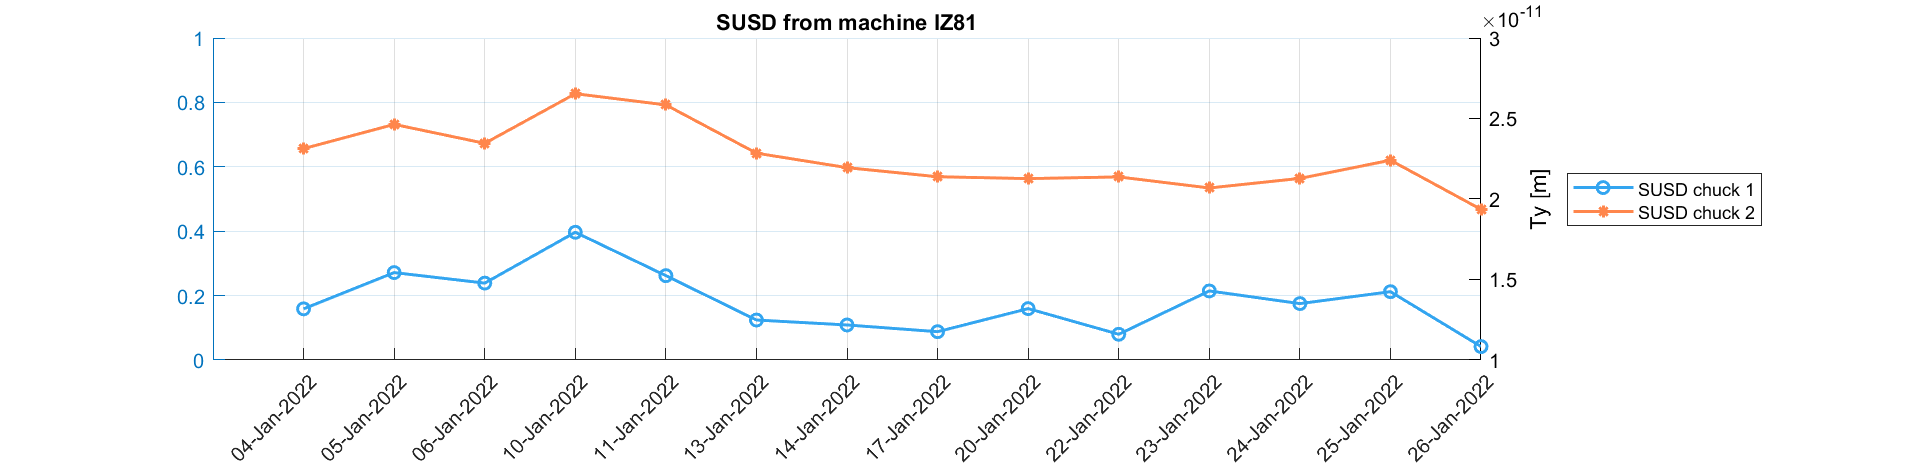

[fig, plt01] = trendLinePlot(dates, ...
                             {values(:,1), values(:,2)}, ...
                             'valuesDescription', {'SUSD chuck 1', 'SUSD chuck 2'}, ...
                             'figureTitle', 'SUSD from machine IZ81', ...
                             'figureUnit', 'Ty [m]');

Similarly, we can make a bar plot using trendBarPlot. By using the 'useFigure' argument, the bar plot may be added to the same figure.

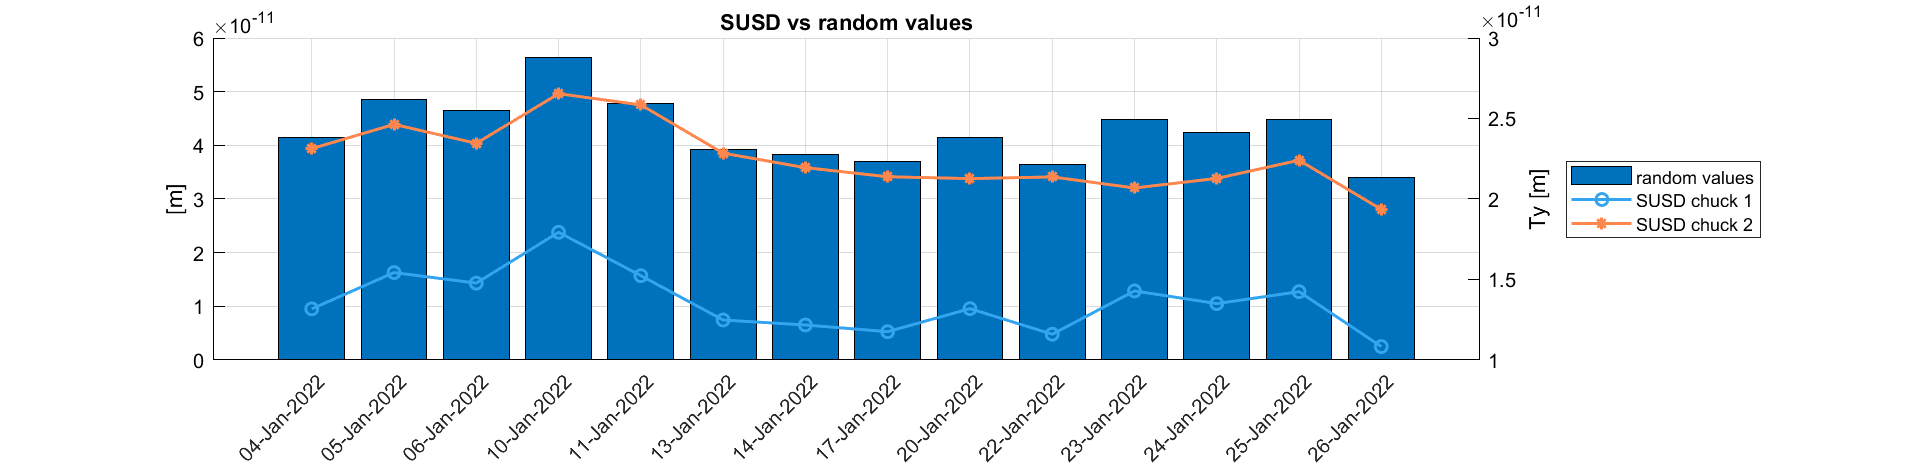

[fig, plt02] = trendBarPlot(dates, ...
                            {pi * values(:,1)}, ...
                            'valuesDescription', {'random values'}, ...
                            'figureTitle', 'SUSD vs random values', ...
                            'figureUnit', '[m]', ...
                            'useFigure', fig);

## Additional Plotting

Suppose now that we have additional datasets (again for SUSD) that include negative numbers, that we would like to plot in the same graph. Since the data is for the same chuck, it makes sense to plot them in the same color. This requires the reset using 'resetColors'.

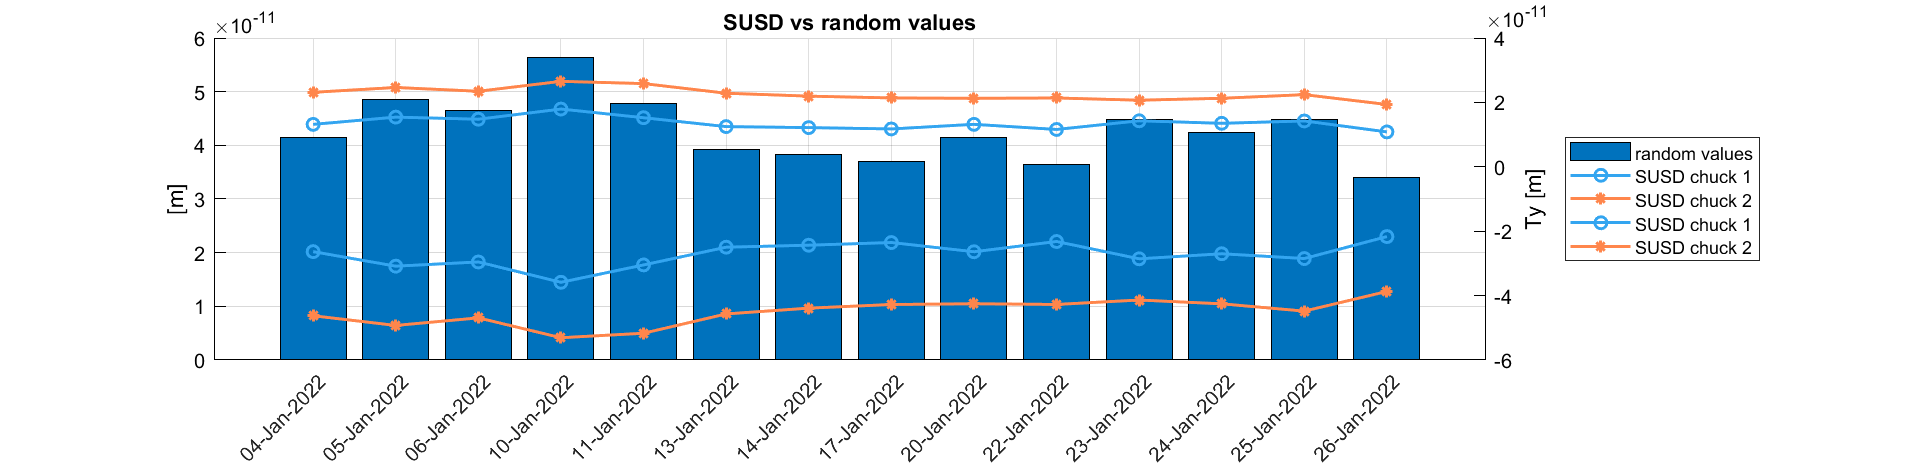

resetColors;

[fig, plt03] = trendLinePlot(dates, ...
                             {-2 * values(:,1), -2 * values(:,2)}, ...
                             'valuesDescription', {'SUSD chuck 1', 'SUSD chuck 2'}, ...
                             'useFigure', fig);

Finally, we make a last trendbarplot, ensuring that the legend, title and axes are specified correctly and consistently when adding the plots to the figure.

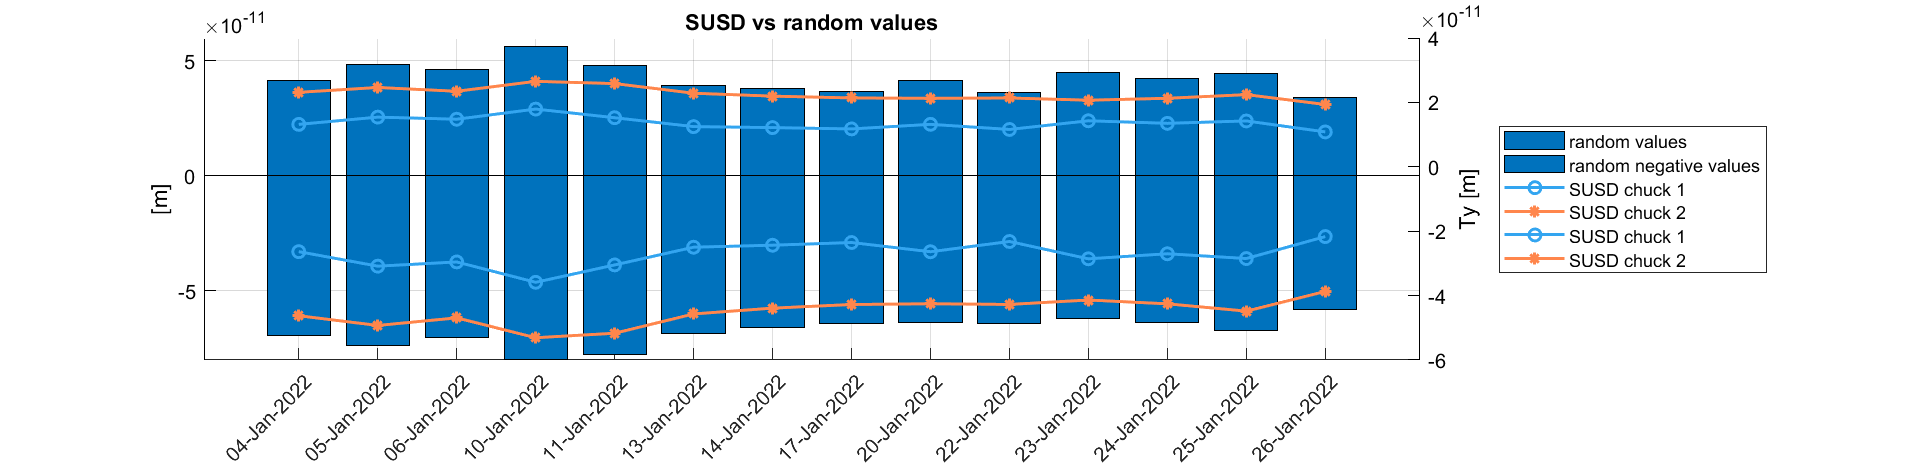

[fig, plt04] = trendBarPlot(dates, ...
                            {-3 * values(:,2)}, ...
                            'valuesDescription', {'random negative values'}, ...
                            'figureTitle', 'SUSD vs random values', ...
                            'figureUnit', '[m]', ...
                            'useFigure', fig);

Lastly, it may be useful to store the plots such that they can be manipulated manually later.

plt = [plt01, plt02, plt03, plt04];

## generateSomeData

This is the subfunction that is used for generating the plotting data.

function [dates, values] = generateSomeData

% Example dates (taken from IZ81)
dates = datetime({'04-Jan-2022 19:29:08'; ...
                  '05-Jan-2022 21:51:20'; ...
                  '06-Jan-2022 16:36:21'; ...
                  '10-Jan-2022 09:13:48'; ...
                  '11-Jan-2022 14:56:45'; ...
                  '13-Jan-2022 08:42:30'; ...
                  '14-Jan-2022 16:34:54'; ...
                  '17-Jan-2022 18:40:21'; ...
                  '20-Jan-2022 20:52:06'; ...
                  '22-Jan-2022 20:52:33'; ...
                  '23-Jan-2022 17:11:07'; ...
                  '24-Jan-2022 09:11:42'; ...
                  '25-Jan-2022 13:21:50'; ...
                  '26-Jan-2022 14:35:49'});

% Example values (SUSD -Ty from CHK1/2 of IZ81)
values = [1.31771303474664e-11, 2.31296098830902e-11; ...
          1.54296448426523e-11, 2.46348992252408e-11; ...
          1.47759443254531e-11, 2.34576710596945e-11; ...
          1.79343094933035e-11, 2.65400147580757e-11; ...
          1.52391607110516e-11, 2.58444804896776e-11; ...
          1.24834598414933e-11, 2.28461377993295e-11; ...
          1.21753703082475e-11, 2.19465986169562e-11; ...
          1.17586663141746e-11, 2.13826076930040e-11; ...
          1.31905219224937e-11, 2.12672238704952e-11; ...
          1.15989431796966e-11, 2.13711455167072e-11; ...
          1.42893943541271e-11, 2.06851018305920e-11; ...
          1.35032748861329e-11, 2.12792980962246e-11; ...
          1.42429348283904e-11, 2.24084513606802e-11; ...
          1.08332155640301e-11, 1.93547259726834e-11];
      
end